## Problem 1 (15 points)

For each of the following distributions, do:

(i) plot the probability density function (PDF) based on the analytical expression. The PDF must appear smooth enough and without apparent signs of discretization.

(ii) plot the cumulative distribution function (CDF) using Riemann-sum approximation. The CDF must appear smooth enough and without apparent signs of discretization.

(iii) use Riemann-sum approximations to compute the approximate variance (if finite) within a tolerance of 0.01 of its true value known analytically.

### Part 1 [6 points: 1 + 2 + 3]

Laplace PDF ( en.wikipedia.org/wiki/Laplace_distribution#Probability_density_function ) with location parameter µ := 2 and scale parameter b := 2 .

%(i)
mu = 2;
b = 2;
fplot(@(x) laplacePDF(x,mu,b),[-10 10])

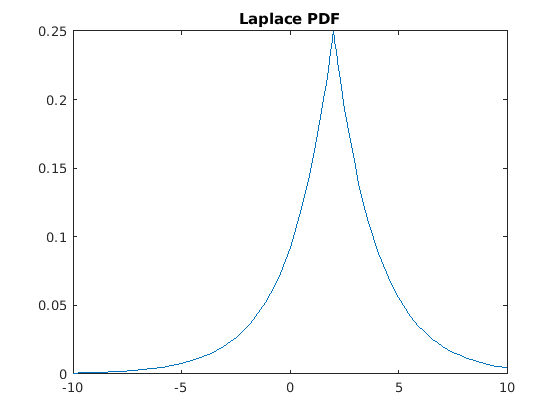

title('Laplace PDF');

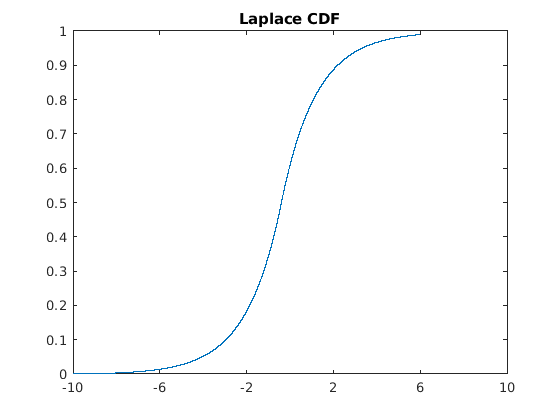


%(ii)

%riemannCDF is a function which takes in another function and an interval as an argument
%and returns cdf(an array of cdf values in that interval)
cdf = riemannCDF(@(x) laplacePDF(x,mu,b), [-10 10]);
plot(cdf)
xticklabels([-10:4:10])
title('Laplace CDF');


%(iii)

%riemannVariance is a function which takes in another function and an
%interval as an argument and returns the variance of the ditribution in
%that interval
empirical_variance = riemannVariance(@(x) laplacePDF(x,mu,b), [-100 100])

empirical_variance = 8.0000

true_variance = 2*b^2 % Used from wikipedia

true_variance = 8

### Part 2 [6 points: 1 + 2 + 3]

Gumbel PDF ( en.wikipedia.org/wiki/Gumbel_distribution ) with location parameter µ := 1 and scale parameter β := 2 .

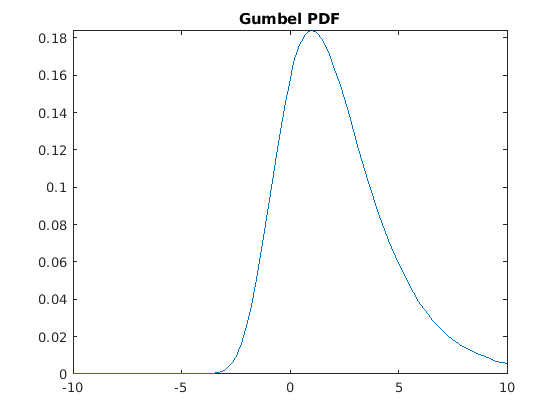

%(i)
mu = 1;
beta = 2;
fplot(@(x) gumbelPDF(x,mu,beta),[-10 10])
title('Gumbel PDF');

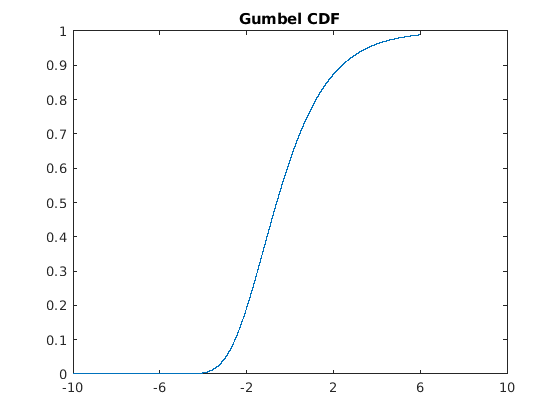


%(ii)
cdf = riemannCDF(@(x) gumbelPDF(x,mu,beta), [-10 10]);
plot(cdf)
xticklabels([-10:4:10])
title('Gumbel CDF');


%(iii)
empirical_variance = riemannVariance(@(x) gumbelPDF(x,mu,beta), [-100 100])

empirical_variance = 6.5797

true_variance = pi^2*beta^2/6 % Used from wikipedia

true_variance = 6.5797

### Part 3 [3 points: 1 + 2]

Cauchy PDF ( en.wikipedia.org/wiki/Cauchy_distribution#Probability_density_function ) with location parameter  $x_0$:= 0 and scale parameter γ := 1 .

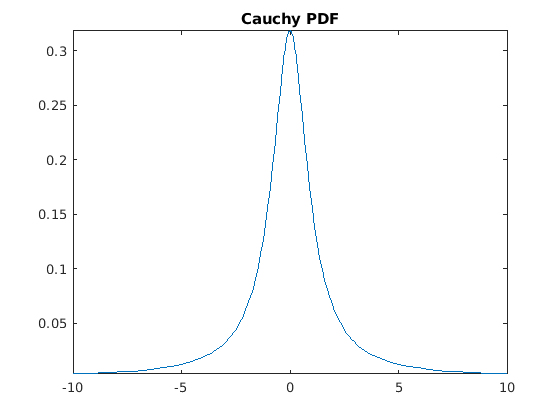

%(i)
xo = 0;
y = 1;
fplot(@(x) cauchyPDF(x,xo,y),[-10 10])
title('Cauchy PDF');

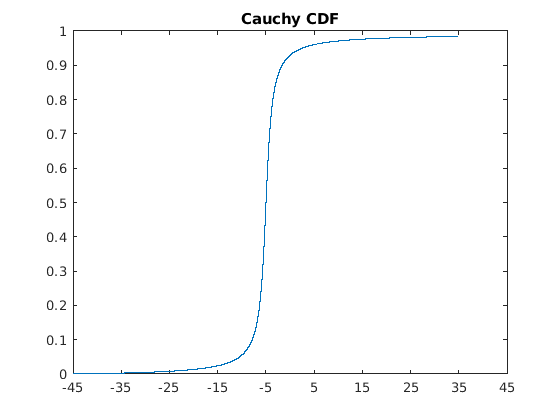


%(ii)
cdf = riemannCDF(@(x) cauchyPDF(x,xo,y), [-40 40]);
plot(cdf)
xticklabels([-45:10:45])
title('Cauchy CDF');

riemannVariance :=

function var = riemannVariance(func, range)
    dx = 10^-3; % range is divided into n small intervals of size dx
    n = (range(2) - range(1))/dx;
    x = range(1);
    s1 = 0; % s1 is E[X]
    s2 = 0; % s2 is E[X^2]
    for i = 1:n % iteration over each interval to find the integration discretly (as a sum)
        s1 = s1 + x*func(x)*dx;
        s2 = s2 + x^2*func(x)*dx;
        x = x + dx;
    end
    var = s2 - s1^2; % empiraical variance found using E[X] and E[X^2]
end

riemannCDF :=

function y = riemannCDF(func, range)
    dx = 10^-3; % range is divided into n small intervals of size dx
    n = (range(2) - range(1))/dx;
    x = range(1);
    s = [0]; % assumption -- cdf value at minimum of range input is 0
    for i = 1:n
        s = [s s(end)+func(x)*dx]; % consecutive cdf values found using summation of small rect. area
        x = x + dx;
    end 
    y = s; % output is an array of cdf values 
end

Cauchy PDF := 

function y = cauchyPDF(x,xo,gamma)
    y = 1./(pi.*gamma.*[1+((x-xo)./gamma).^2]); % function found from wikipedia
end

Gumbel PDF :=

function y = gumbelPDF(x,mu,beta)
    stdx = (x-mu)./beta;
    y = exp(-stdx).*exp(-exp(-stdx))./beta; %function found from wikipedia
end

Laplace PDF :=

function y = laplacePDF(x,mu,b)
    y = (exp(-abs(x-mu)./b))./(2*b); %function found from wikipedia
end